## Intro

This is a testbench for processing the IRMAS data set for musical instrument identification, with the goal of testing different feature extraction and modeling algorithms. The methods below follow a paper titled "Audio Signal Classification Based on Optimal Wavelet and Support Vector Machine" (https://ieeexplore.ieee.org/abstract/document/4426756).

## Signal Capture

For this project, we are obtaining our signal data from the IRMAS database. This script will focus on training data for now. A testing script will be put together later in the project development phase.

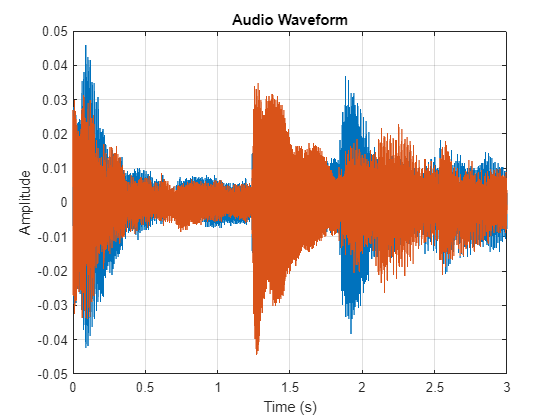

%% Import testing data
plotsEnabled = true;
testmode = "Single File";

if(testmode=="Single File")
    % Single file test
    file_path = '.\IRMAS-TrainingData\pia\[pia][cla]1283__1.wav';
    
    % Read the audio data from the .ogg file
    [audio_data, sample_rate] = audioread(file_path);
    
    % Duration of the audio in seconds
    audio_duration = length(audio_data) / sample_rate;
    
    % Plot the audio waveform
    if(plotsEnabled==true)
        t = (0:(length(audio_data) - 1)) / sample_rate; % Time vector
        figure;
        plot(t, audio_data);
        xlabel('Time (s)');
        ylabel('Amplitude');
        title('Audio Waveform');
        grid on;
    end
    
    % For easier processing we vectorize the stereo data. Converting to
    % mono could possibly distort or remove information we need.
    audio_data_vectorized = reshape(audio_data(:, :, 1), [], 1);
end

## Data Conditioning

Data has to be prepared before we perform feature extraction. This process follows three steps per the paper referenced in the Intro:

- Frame Forming

- Pre-emphasized Filter

- Energy of frames and Threshold

### Frame Forming

This process will take the audio data and break it into frames. Per the paper we are following, the frames should be 512 samples with an overlap of 75%.

% Parameters
% doFrameForming=true; % Useful when audio clips are long

% Frame forming 

frameLength = 512;
frameOverlap = 0.75;
frameOverlapInSamps = floor(frameLength*frameOverlap);
sampIncrement = frameLength - frameOverlapInSamps;

% It's possible that the audio data won't evenly divide into frames
% with a length of 512. Before framing, we calculate the number of
% frames needed, and then zero pad that last one.
framesPerVector = length(audio_data_vectorized)/frameLength; % Assumes no overlap
numFrames=ceil(framesPerVector/(1-frameOverlap)); % Accounts for overlap
framed_audio = zeros(frameLength,numFrames);

% Populate the frames into matrix
k = 1;
currSample = 1;
while(k<=numFrames)
    try
        framed_audio(:,k) = audio_data_vectorized(currSample:currSample+frameLength-1);
    catch
        numMissingSamps = frameLength - length(audio_data_vectorized(currSample:end));
        zeroPaddedFrame = zeros(numMissingSamps,1);
        framed_audio(:,k) = [audio_data_vectorized(currSample:end);zeroPaddedFrame];
    end
    currSample = currSample+sampIncrement;
    k=k+1;
end


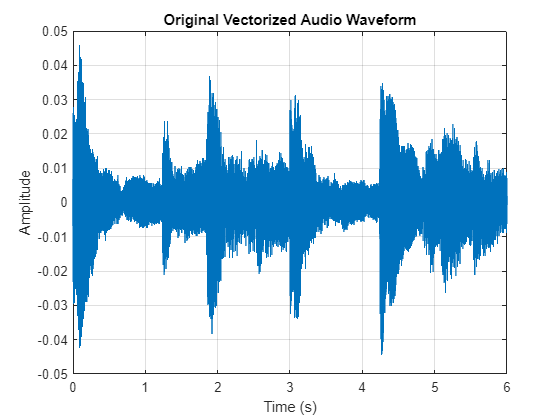

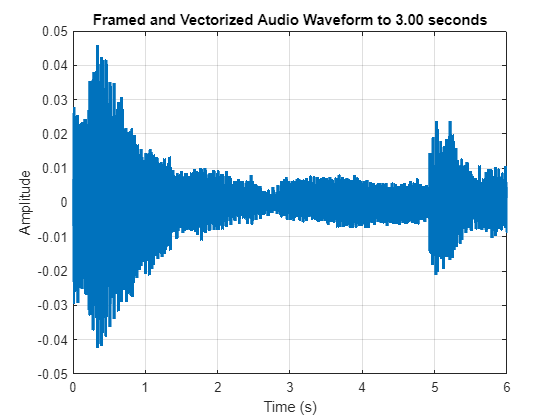

% Pre-emphasized filtering



% preprocessed_audio = reshape(framed_audio(:, :, 1), [], 1);


% Plot the preprozessed audio waveform
if(plotsEnabled==true)
    t = (0:(length(audio_data_vectorized) - 1)) / sample_rate; % Time vector
    figure;

    plot(t, audio_data_vectorized);
    xlabel('Time (s)');
    ylabel('Amplitude');
    title('Original Vectorized Audio Waveform');
    grid on;

    t = (0:(length(audio_data_vectorized) - 1)) / sample_rate; % Time vector
    figure;
    plot(t, preprocessed_audio(1:length(audio_data_vectorized)));
    xlabel('Time (s)');
    ylabel('Amplitude');
    title(sprintf('Framed and Vectorized Audio Waveform to %.2f seconds', audio_duration));
    grid on;
end


## Feature Extraction

## Modeling and Prediction